%Sergio Andrés García Morán
%1001300253

%#### = 0

%link de conversacion
% https://chatgpt.com/share/1558580a-bd82-45cb-be25-5d98446d2c9c 

Exponencial

fprintf('Datos suministrados por chatgpt')

Datos suministrados por chatgpt

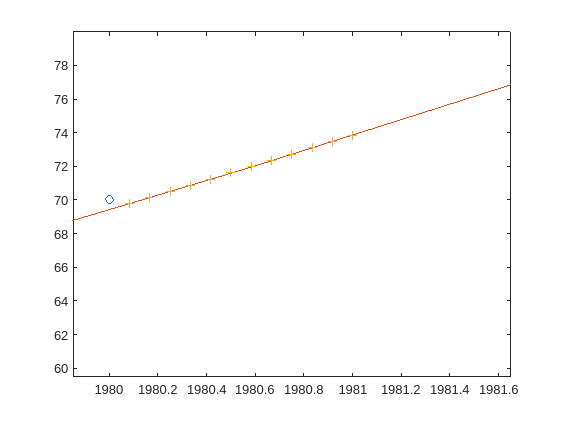


% Año
anio = [1970, 1975, 1980, 1985, 1990, 1995, 2000, 2005, 2010, 2015, 2020];

% Número de Casos Diagnosticados de diabetes tipo 2 (en millones)
casos_diagnosticados = [30, 50, 70, 100, 150, 200, 250, 350, 450, 550, 700];

plot(anio, casos_diagnosticados, 'o');

syms x;

[a4,a5] = regresion_exponencial(anio,casos_diagnosticados);
funct = a4*exp(a5*x);

hold on;
x1 = linspace(anio(1), anio(length(anio)), 100);
y1 = subs(funct, x, x1);
plot(x1,y1, '-');

[meses_1980, mes_1980] = calc_meses(funct, 1980);
[meses_1990, mes_1990] = calc_meses(funct, 1990);
[meses_2010, mes_2010] = calc_meses(funct, 2010);
[meses_2020, mes_2020] = calc_meses(funct, 2020);

plot(mes_1980, meses_1980, '+');
plot(mes_1990, meses_1990, '*');
plot(mes_2010, meses_2010, 'diamond');
plot(mes_2020, meses_2020, 'pentagram');

hold off;

Potencial

fprintf('Datos suministrados por chatgpt')

Datos suministrados por chatgpt


% Año
anio2 = [1970, 1975, 1980, 1985, 1990, 1995, 2000, 2005, 2010, 2015, 2020];

% Prevalencia de Obesidad (%)
prevalencia_obesidad = [14.5, 15.0, 15.3, 18.4, 23.3, 25.1, 30.5, 34.3, 35.7, 39.6, 42.4];


plot(anio2, prevalencia_obesidad, 'o');

syms x;

[a2,a3] = regresion_potencial(anio2,prevalencia_obesidad);
func = a2*x^a3;

hold on;
x2 = linspace(anio2(1), anio2(length(anio2)), 100);
y2 = subs(func, x, x2);
plot(x2, y2, '-');

[meses_1980, mes_1980] = calc_meses(func, 1980);
meses_1980

meses_1980 =    17.3346
   17.3699
   17.4052
   17.4406
   17.4761
   17.5116
   17.5472
   17.5828
   17.6186
   17.6544


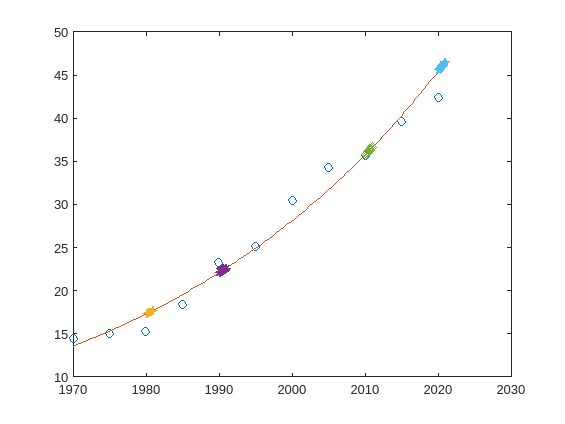

[meses_1990, mes_1990] = calc_meses(func, 1990);
[meses_2010, mes_2010] = calc_meses(func, 2010);
[meses_2020, mes_2020] = calc_meses(func, 2020);

plot(mes_1980, meses_1980, '+');
plot(mes_1990, meses_1990, '*');
plot(mes_2010, meses_2010, 'diamond');
plot(mes_2020, meses_2020, 'pentagram');

hold off;

Funciones

function [res, meses] = calc_meses(fun, anio)
    syms x;
    res = zeros(12,1);
    meses = zeros(12,1);
    for i=1:12
        mes = i/12;
        res(i) = subs(fun, x, (anio+mes));
        %Como la funcion de aproximacion se realizo a partir de los valores
        %por año, para calcular los meses se hace una proporcion en donde
        %cada mes corresponde a 1/12 de cada año. De esta forma, para
        %calcular los meses del año se deben ir sumando i/12 a cada año
        %donde i representa el numero del mes que se quiere calcular.
        %(Ejemplo: i=1 es enero)
        meses(i) = anio+mes;
    end
end

function [a0,a1] = regresion_lineal(xi,yi)
    n = length(xi);
    a1 = (length(xi)*sum(xi.*yi)-sum(xi)*sum(yi))/(n*sum(xi.^2)-(sum(xi))^2);
    a0 = mean(yi)-a1*mean(xi);
end

function [a0,a1] = regresion_exponencial(xi,yi)
    x2 = xi;
    y2 = log(yi);
    
    [A0,A1] = regresion_lineal(x2,y2);

    a1 = A1;
    a0 = exp(A0);
    %funct(x)= A0*exp(A1*x);
end

function [a0,a1] = regresion_potencial(xi,yi)
    x2 = log10(xi);
    y2 = log10(yi);
    
    [A0,A1] = regresion_lineal(x2,y2);
    a1 = A1;
    a0 = 10^A0;
    %funct(x)= A0*x^A1;
end